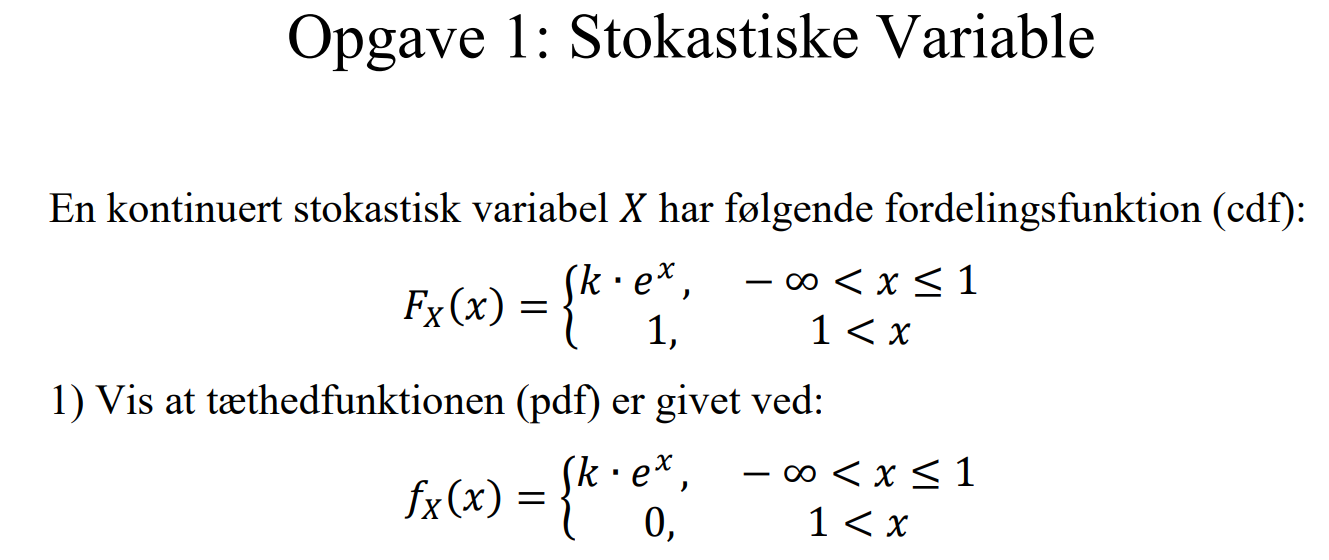

Løst i mathcad prime 4.0 

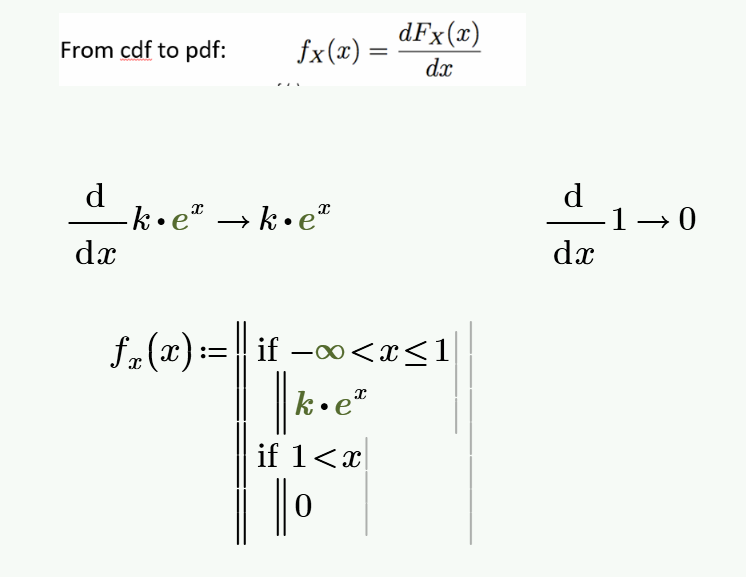

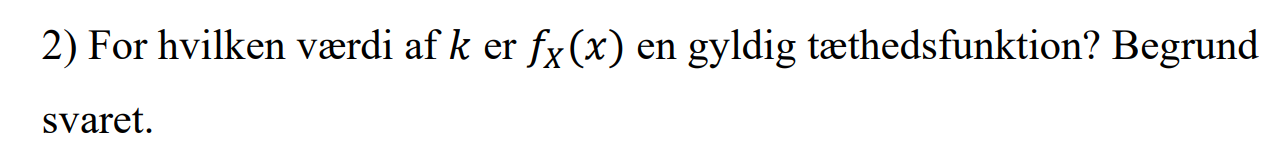

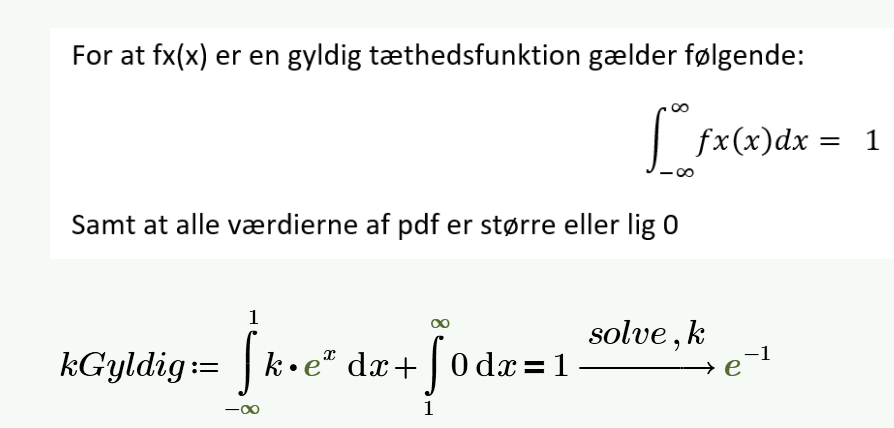

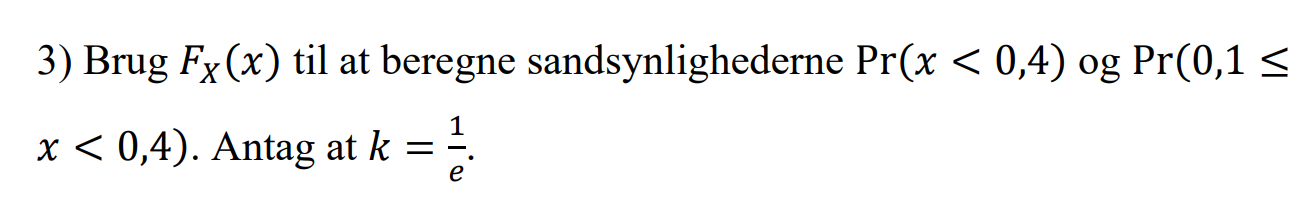

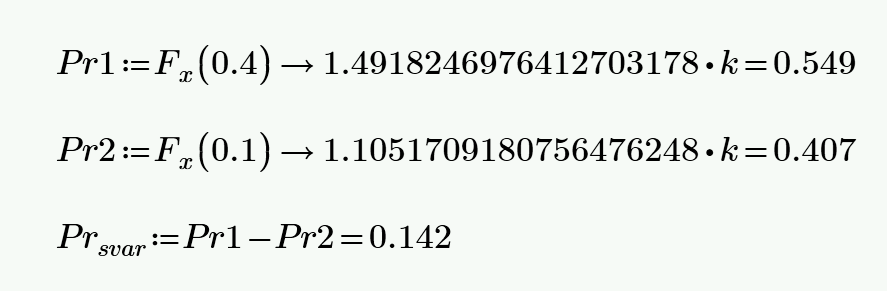

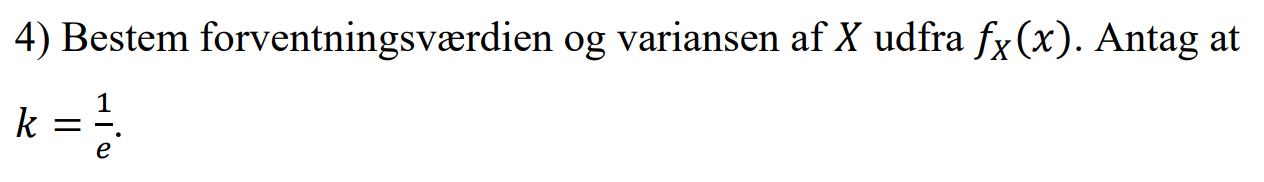

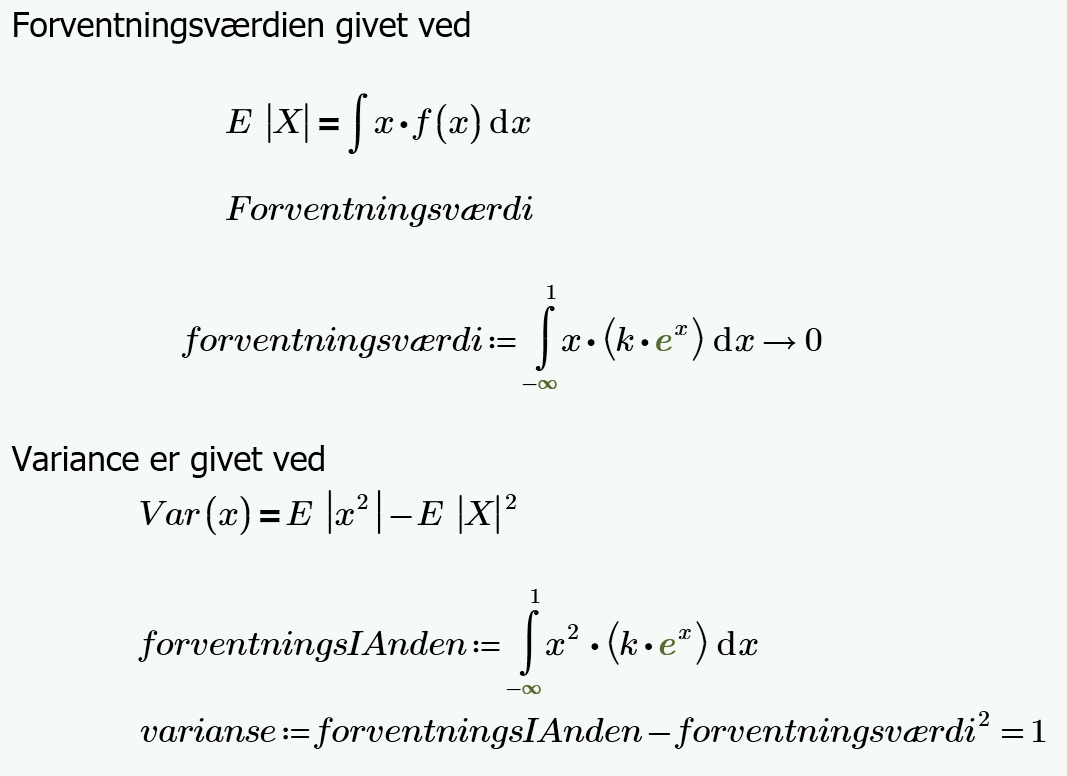

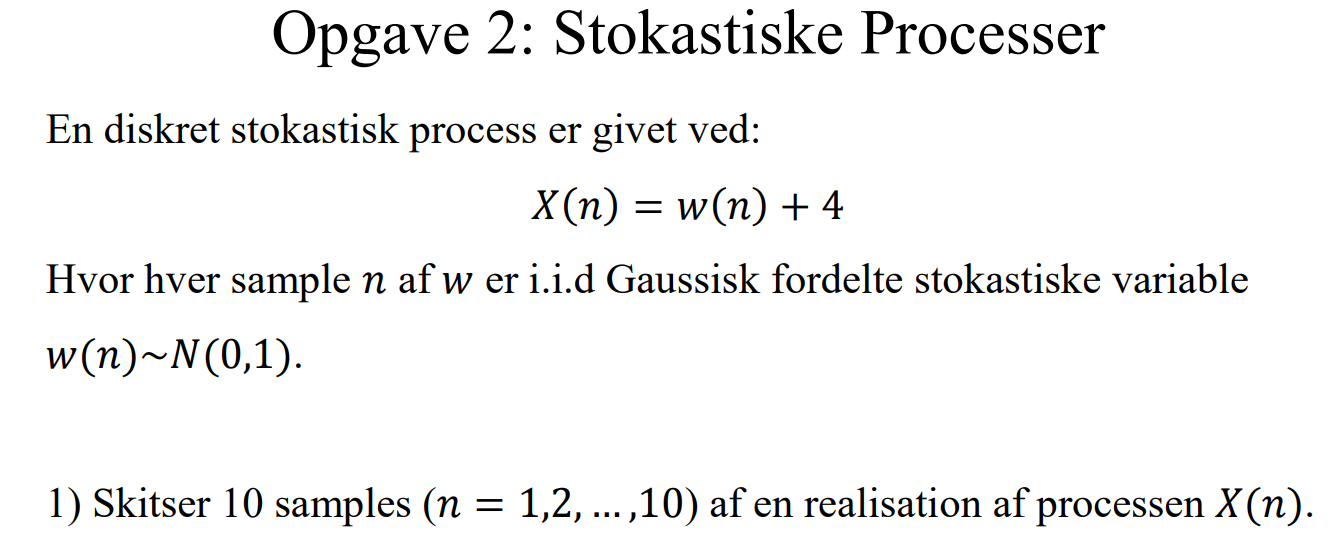

clear all
clc
n = 1:1:10

n =      1     2     3     4     5     6     7     8     9    10


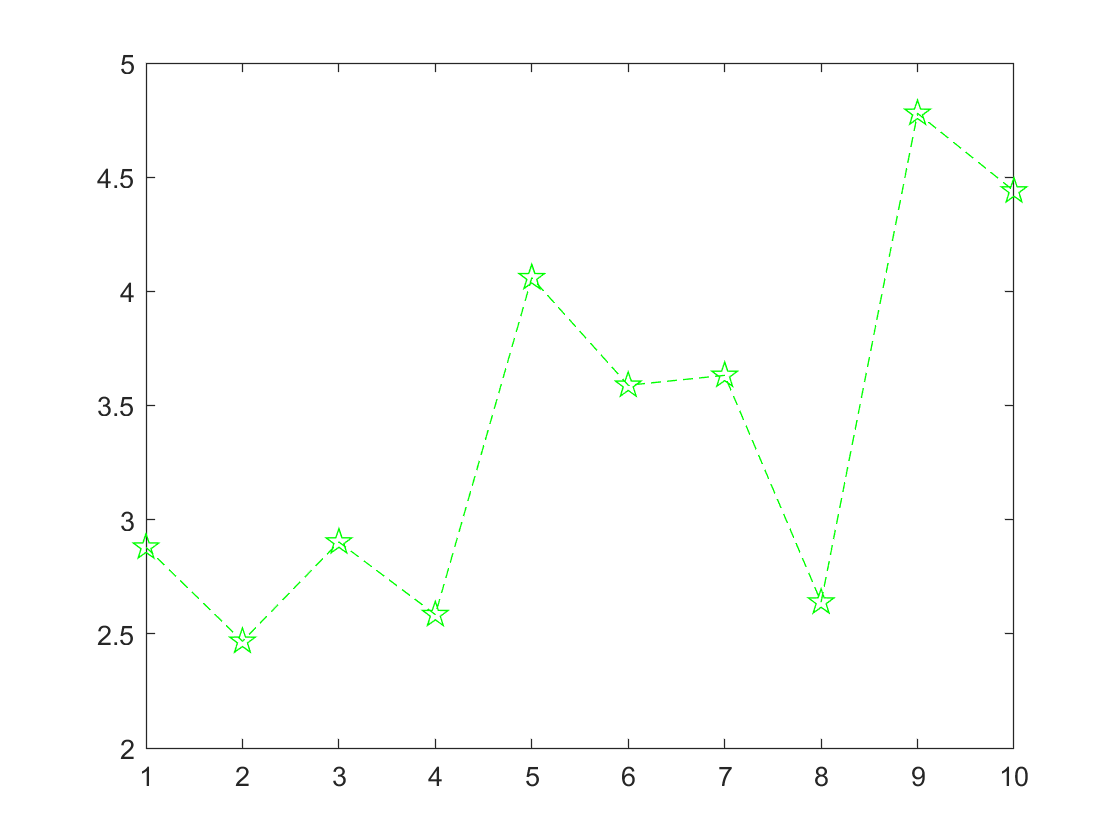


for(n = 1:10)
    X(n) = randn+4;
end
figure(1)
plot(X,'--gp','MarkerSize',10)

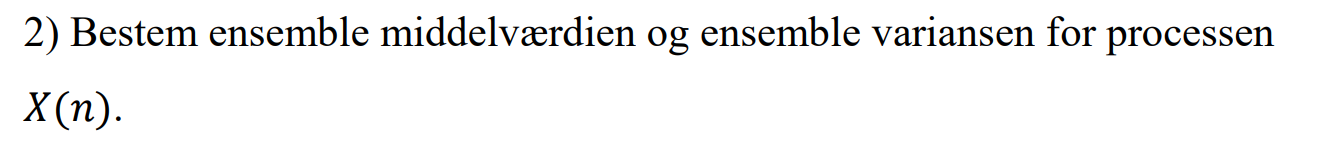

Da ensemble middelværdi ved w(n)~N(0,1) er 0 pga normalfordelingsfunktionen, og +4 ved den givne stokastiske process

Så  gives dette 

EnsembleMean = 0 + 4

EnsembleMean =      4


Variance er givet ved

 

 ensemble variansen ved w(n)~N(0,1) er 1 pga normalfordelingsfunktionen

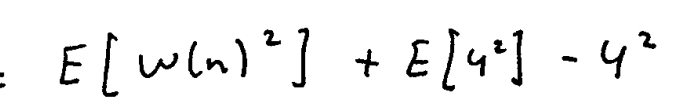

ensembleMean = 1^2+4^2-EnsembleMean^2

ensembleMean =      1


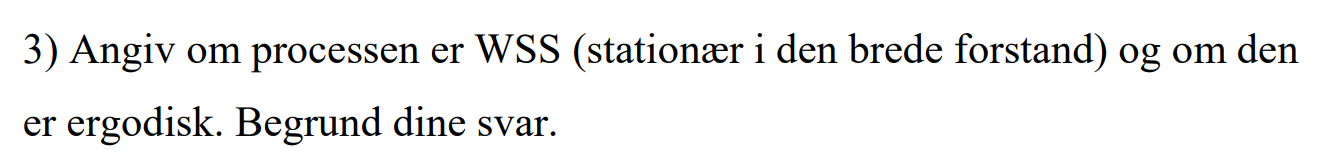

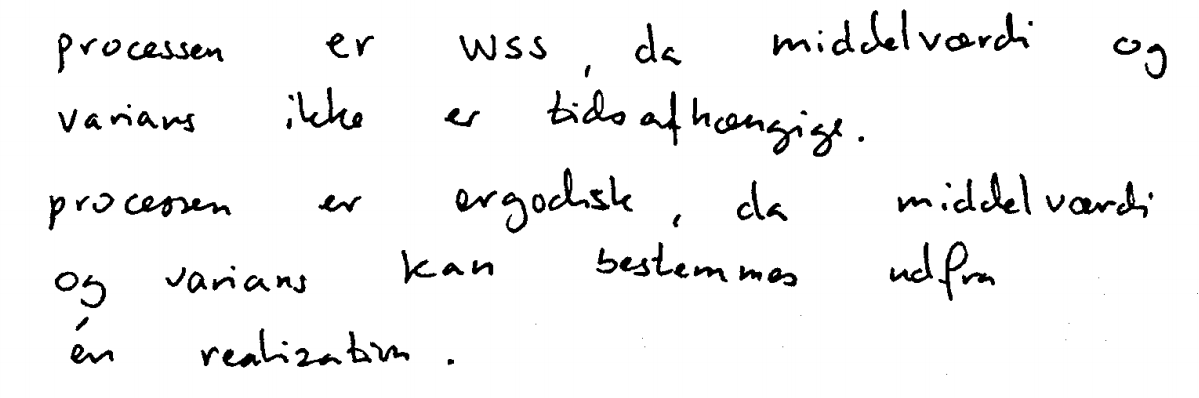

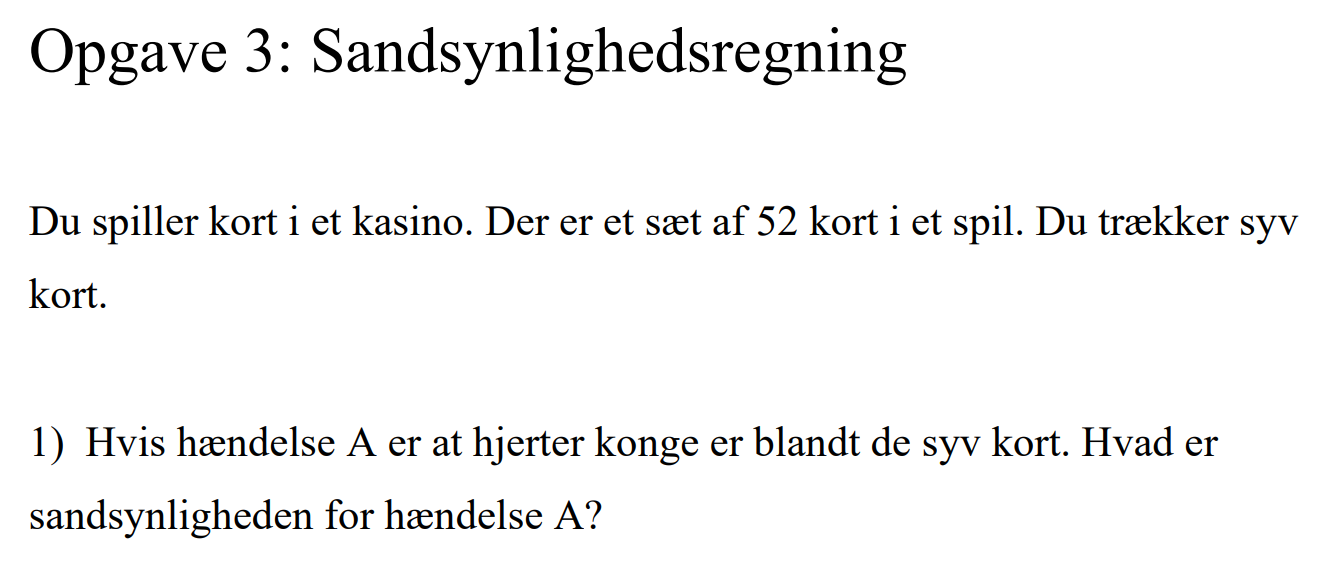

Pr_a =  1/52 + 1/52 + 1/52 + 1/52 + 1/52 + 1/52 + 1/52

Pr_a =    0.134615384615385


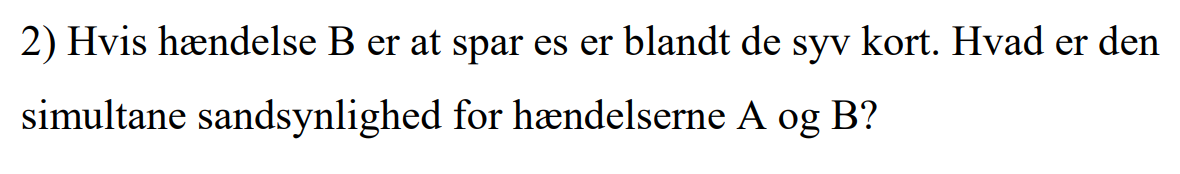

Pr_b =  Pr_a

Pr_b =    0.134615384615385


PrBgivetA = 6 * 1/51

PrBgivetA =    0.117647058823529


PrA_B = PrBgivetA * Pr_b

PrA_B =    0.015837104072398


eq(Pr_a*Pr_b,PrA_B)

ans = logical
   0


Da disse er ikke ens, så kan vi bekræfte at de ikke er uafhænige.

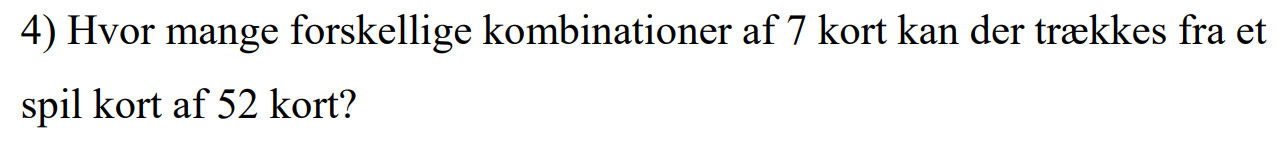

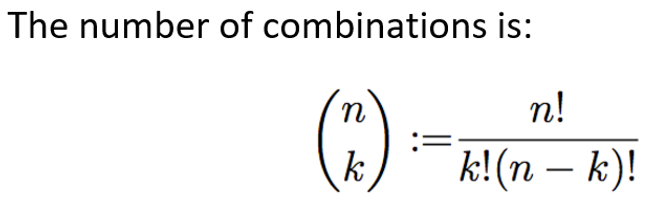

factorial(52)/(factorial(7)*factorial(52-7))

ans =    133784560


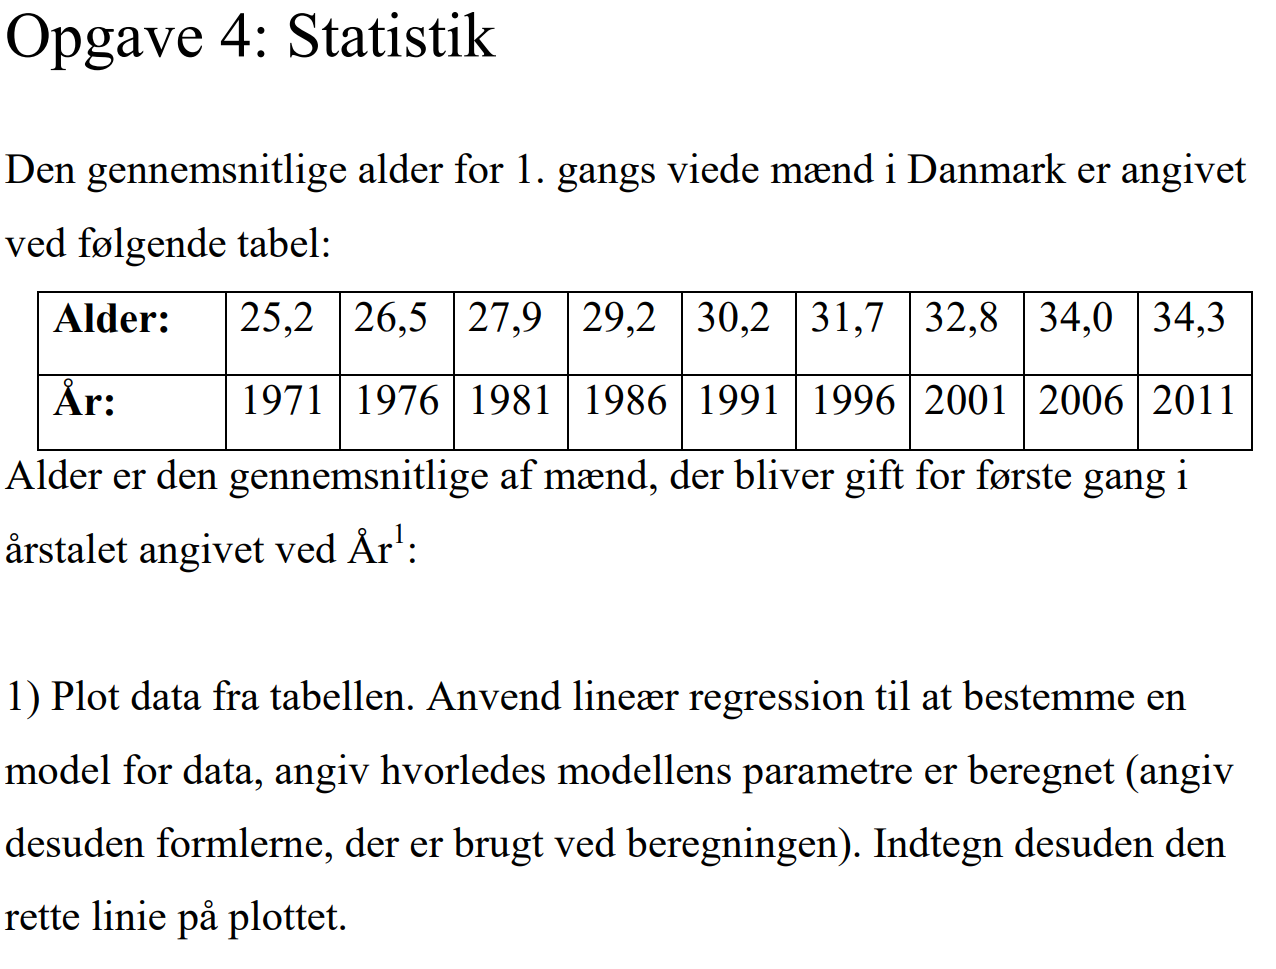

Alder = [25.2 26.5 27.9 29.2 30.2 31.7 32.8 34.0 34.3]

Years = 1971:5:2011

Alder = [25.2 26.5 27.9 29.2 30.2 31.7 32.8 34.0 34.3];
Years = 1971:5:2011;
alderMean = mean(Alder)

alderMean =   30.200000000000003


yearsMean = mean(Years)

yearsMean =         1991


Benytter følgende formel for at finde skæringen og hældningen

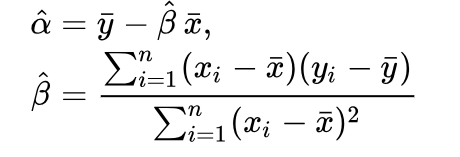

%Parameter estimat hældning
Beta = sum((Alder - alderMean) .* (Years - yearsMean)) / sum((Years - yearsMean).^2)

Beta =    0.237333333333333



% Parameter estimat skæring
Alpha = alderMean - Beta * yearsMean

Alpha =     -4.423306666666666e+02


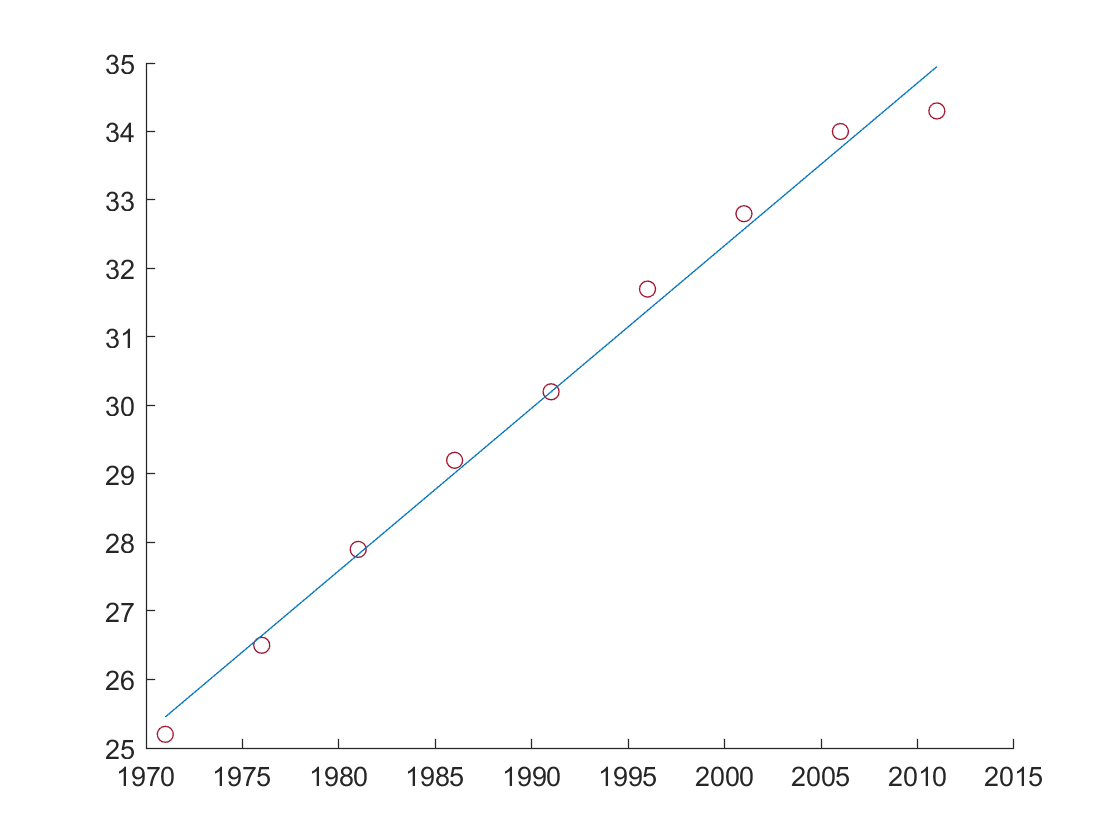

linearModel = Alpha + Years * Beta;
figure(2)
hold on
scatter(Years, Alder)
plot(Years,linearModel)

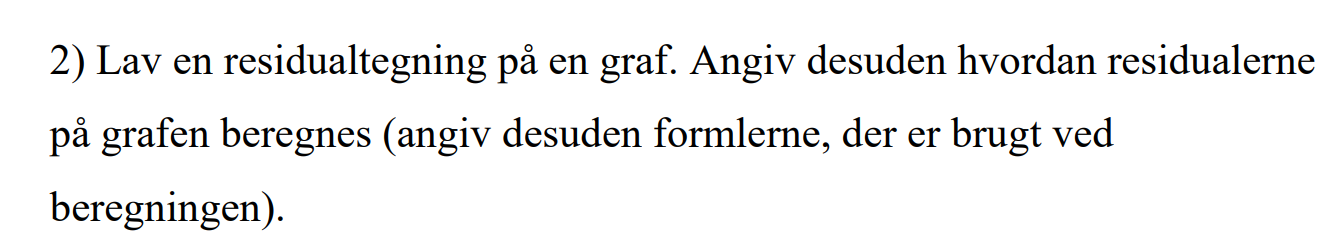

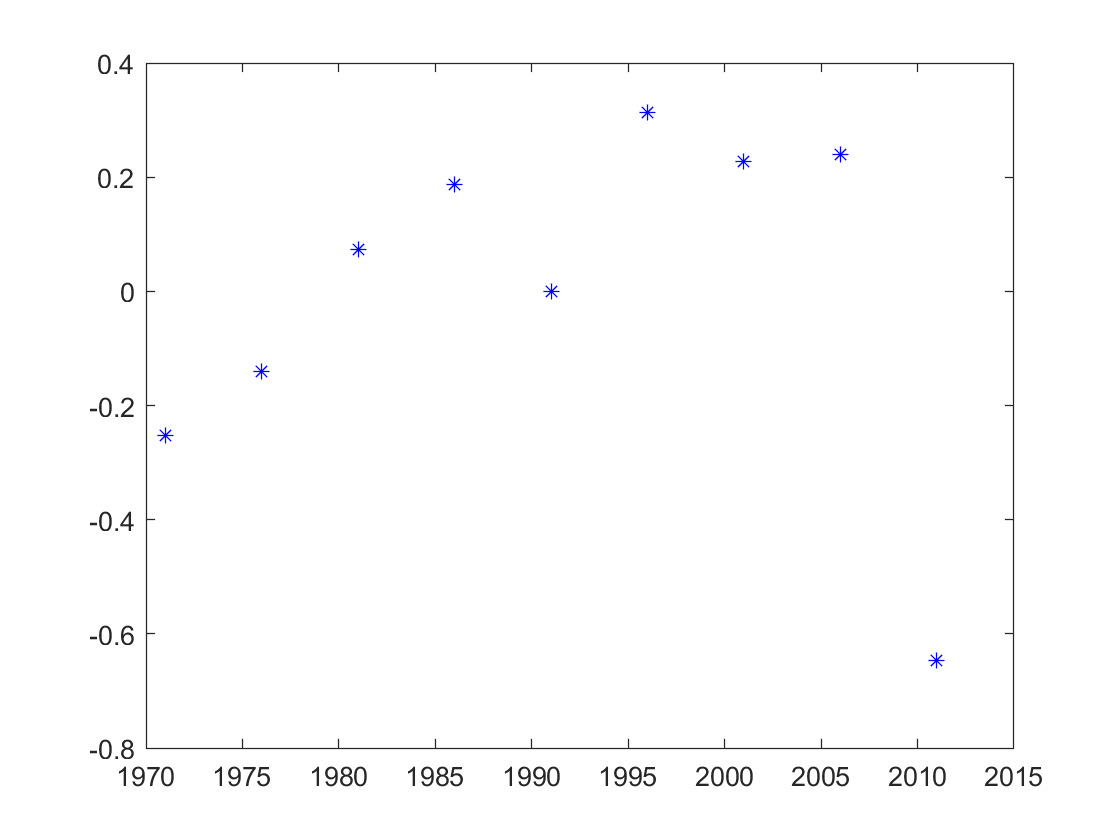

Residualtegning = Alder - linearModel;
figure(3)
plot(Years,Residualtegning,'b*')